# Simulate Field-Oriented Control (FOC) of PMSM

In this exercise, we will collect data from the speed regulation of a surface-mounted permanent magnet synchronous motor (PMSM) using field-oriented control (FOC). FOC is a control scheme in which a d-q coordinates reference frame that is locked to the motor flux space vector is used to achieve decoupling between the motor flux and torque. Consequently, they can be separately controlled by stator direct-axis and quadrature-axis currents, respectively.

## Motor used here is based on BR2804-1700KV-1

We will start with running a parameterize model with the instrumented tests on a motor. 

- PWM Switching frequency

PWM_frequency 	= 30e3;             %Hz  // converter s/w freq
T_pwm           = 1/PWM_frequency;  %s   // PWM switching time period

- Sample Times

Ts          	= T_pwm;        %sec        // Sample time step for controller
Ts_simulink     = T_pwm/2;      %sec        // Simulation time step for model simulation
Ts_motor        = T_pwm/2;      %Sec        // Simulation sample time
Ts_inverter     = T_pwm/2;      %sec        // Simulation time step for average value inverter
Ts_speed        = 30*Ts;        %Sec        // Sample time for speed controller

- Set data type for controller

dataType = 'single';            % Floating point 

- System Parameters // Hardware parameters

% Set Target Parameters
target.CPU_frequency        = 84e6;					%Hz     // Clock frequency
target.PWM_frequency        = PWM_frequency;   		%Hz     // PWM frequency
target.PWM_Counter_Period   = round(target.CPU_frequency/target.PWM_frequency/2); % //PWM timer counts for up-down counter
target.ADC_Vref             = 3.3;					%V		// ADC voltage reference for LAUNCHXL-F28379D
target.ADC_MaxCount         = 4095;					%		// Max count for 12 bit ADC

- Motor Parameters

pmsm.p      = 7;                            %// Pole Pairs for the motor
pmsm.Rs     = 0.4;              %Ohm        // Stator Resistor
pmsm.Ld     = 0.6e-3;           %H          // D-axis inductance value
pmsm.Lq     = 0.6e-3;           %H          // Q-axis inductance value
pmsm.J      = 4.8018552467e-06; %Kg-m2      // Inertia in SI units
pmsm.B      = 9.6037104933e-06; %Kg-m2/s    // Friction Co-efficient
pmsm.Ke     = 4;                %Bemf Const	// Vpk_LL/krpm
pmsm.Kt     = 0.04103;          %Nm/A       // Torque constant
pmsm.I_rated= 3.5;              %A      	// Rated current (phase-peak)
pmsm.N_max  = 19000;            %rpm        // Max speed
pmsm.PositionOffset = 0.1712;	%PU position// Position Offset
pmsm.QEPSlits       = 1250;     %           // QEP Encoder Slits
pmsm.FluxPM     = (pmsm.Ke)/(sqrt(3)*2*pi*1000*pmsm.p/60); %PM flux computed from Ke
pmsm.T_rated    = (3/2)*pmsm.p*pmsm.FluxPM*pmsm.I_rated;   %Get T_rated from I_rated

pmsm.N_base = 4000; % Motor base speed
pmsm.PositionOffset = 0.1917; % Sensorless not required

- Set inverter details (X-NUCLEO-IHM07M1)

inverter.V_dc          = 24;       				%V      // DC Link Voltage of the Inverter (Required for motor)
inverter.I_trip        = 3.55;       			%Amps   // Max current for trip
inverter.Rds_on        = 2e-3;     				%Ohms   // Rds ON for X-NUCLEO-IHM07M1 (From motor driver chip)
inverter.Rshunt        = 0.33;    				%Ohms   // Rshunt for X-NUCLEO-IHM07M1
inverter.CtSensAOffset = 1665;        			%Counts // ADC Offset for phase-A
inverter.CtSensBOffset = 1943;        			%Counts // ADC Offset for phase-B
inverter.ADCGain       = 1;                     %       // ADC Gain factor scaled by SPI (On board amplification is not possible)
inverter.EnableLogic   = 1;    					% 		// Active high for X-NUCLEO-IHM07M1 enable pin (EN_GATE)
inverter.invertingAmp  = -1;   					% 		// Non inverting current measurement amplifier
inverter.ISenseVref    = 3.3;					%V 		// Voltage ref of inverter current sense circuit
inverter.ISenseVoltPerAmp = 0.505; 				%V/Amps // Current sense voltage output per 1 A current (Rshunt * iSense op-amp gain)
inverter.ISenseMax     = inverter.ISenseVref/(2*inverter.ISenseVoltPerAmp); %Amps // Maximum Peak-Neutral current that can be measured by inverter current sense
inverter.R_board       = inverter.Rds_on + inverter.Rshunt/3;  %Ohms
inverter.ADCOffsetCalibEnable = false;

- Per-Unit System commonly used in electrical engineering to express the values of quantities like voltage, current and power. 

PU_System.V_base   = (inverter.V_dc/sqrt(3));
PU_System.I_base   = inverter.ISenseMax;
PU_System.N_base   = pmsm.N_base;
PU_System.T_base   = (3/2)*pmsm.p*pmsm.FluxPM*PU_System.I_base;
PU_System.P_base   = (3/2)*PU_System.V_base*PU_System.I_base;

acceleration = 20000/PU_System.N_base;                  %  P.U/Sec // Maximum allowable acceleraton

## Open loop reference values

T_Ref_openLoop          = 1;                    % Sec // Time for open-loop start-up
Speed_openLoop_PU       = 0.1;                  % PU  // Per-Unit speed referene for open-loop start-up
Vd_Ref_openLoop_PU      = Speed_openLoop_PU*2;  % Use 1.2x for Dyno setup and 2x for others

## Controller design

PI_params = mcb.internal.SetControllerParameters(pmsm,inverter,PU_System,T_pwm,2*Ts,Ts_speed);

%Updating delays for simulation
PI_params.delay_Currents    = int32(Ts/Ts_simulink);
PI_params.delay_Position    = int32(Ts/Ts_simulink);
PI_params.delay_Speed       = int32(Ts_speed/Ts_simulink);
PI_params.delay_Speed1      = (PI_params.delay_IIR + 0.5*Ts)/Ts_speed;


## Displaying model variables

disp(pmsm);

                 p: 7
                Rs: 0.4000
                Ld: 6.0000e-04
                Lq: 6.0000e-04
                 J: 4.8019e-06
                 B: 9.6037e-06
                Ke: 4
                Kt: 0.0410
           I_rated: 3.5000
             N_max: 19000
    PositionOffset: 0.1917
          QEPSlits: 1250
            FluxPM: 0.0032
           T_rated: 0.1158
            N_base: 4000



disp(inverter);

                    V_dc: 24
                  I_trip: 3.5500
                  Rds_on: 0.0020
                  Rshunt: 0.3300
           CtSensAOffset: 1665
           CtSensBOffset: 1943
                 ADCGain: 1
             EnableLogic: 1
            invertingAmp: -1
              ISenseVref: 3.3000
        ISenseVoltPerAmp: 0.5050
               ISenseMax: 3.2673
                 R_board: 0.1120
    ADCOffsetCalibEnable: 0



disp(target);

         CPU_frequency: 84000000
         PWM_frequency: 30000
    PWM_Counter_Period: 1400
              ADC_Vref: 3.3000
          ADC_MaxCount: 4095



## Open the system model for a quick simulation

Motor Control Blockset for Simulink speeds up the development of a field-oriented controller by helping you to verify control algorithms using simulation and generate compact and efficient code for a microcontroller. 

At a higher level, the system model is illustrated in the figure. 

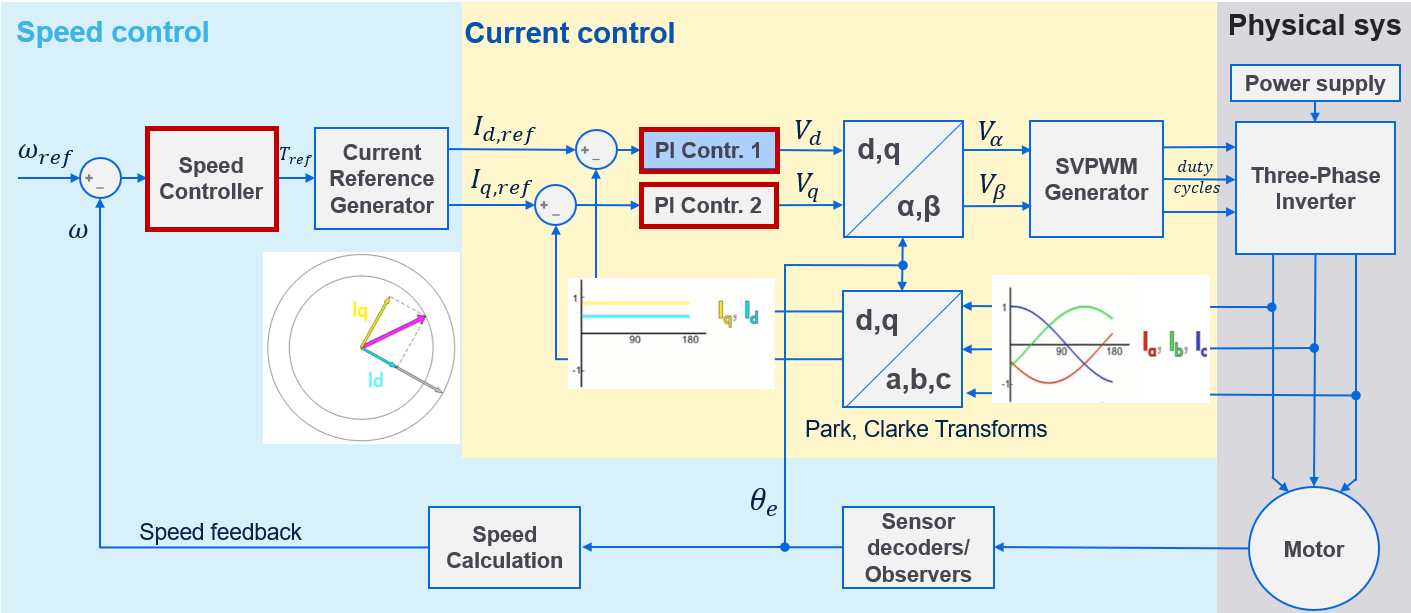

We can open the detailed Simulink model and simulate to collect data of interests to train neural networks.

open_system("FOCforPMSM2Cases"); 
% set case 1
set_param("FOCforPMSM2Cases/Input/Generated Signal/SignalInput","Value", "-1"); 
simOutput = sim("FOCforPMSM2Cases"); 

Failed to find 'mcbcontrolslib/SinCos Embedded Optimized' in library 'mcbcontrolslib' referenced by 'FOCforPMSM2Cases/FOC/Current Control/Sine-Cosine Lookup1'

disp(simOutput.logsout);

### Simulation with different speed reference input

There are two speed reference cases of interests in this example. Use the gadget to observe simulation output from both cases by turning the knob. 

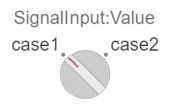

set_param("FOCforPMSM2Cases/Input/Generated Signal/SignalInput", "Value", "1"); 
simOutput_case2 = sim("FOCforPMSM2Cases"); 

Failed to find 'mcbcontrolslib/SinCos Embedded Optimized' in library 'mcbcontrolslib' referenced by 'FOCforPMSM2Cases/FOC/Current Control/Sine-Cosine Lookup1'

disp(simOutput_case2.logsout);